clear
clc
format long


train1 = readmatrix('motor1.xlsx');
train2 = readmatrix('motor2.xlsx');

x_train1 = train1(:, 1);
y_train1 = train1(:, 2);
x_train2 = train2(:, 1);
y_train2 = train2(:, 2);

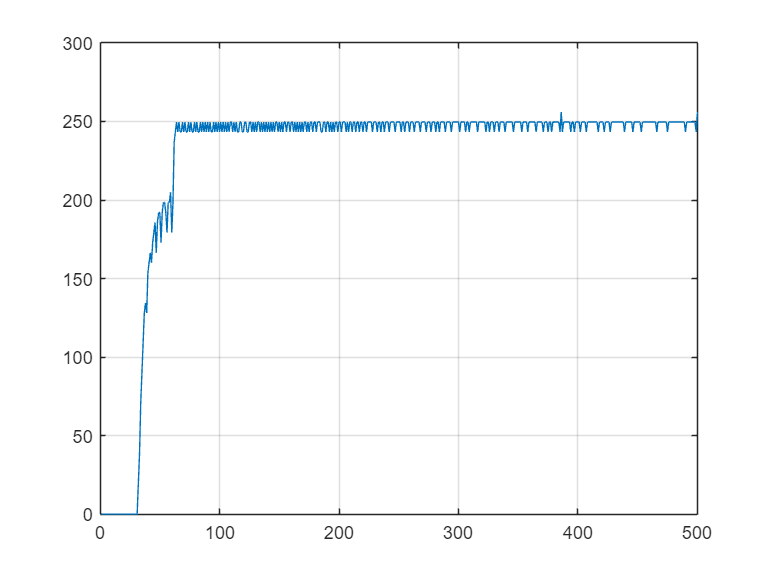

plot(y_train1);
grid on

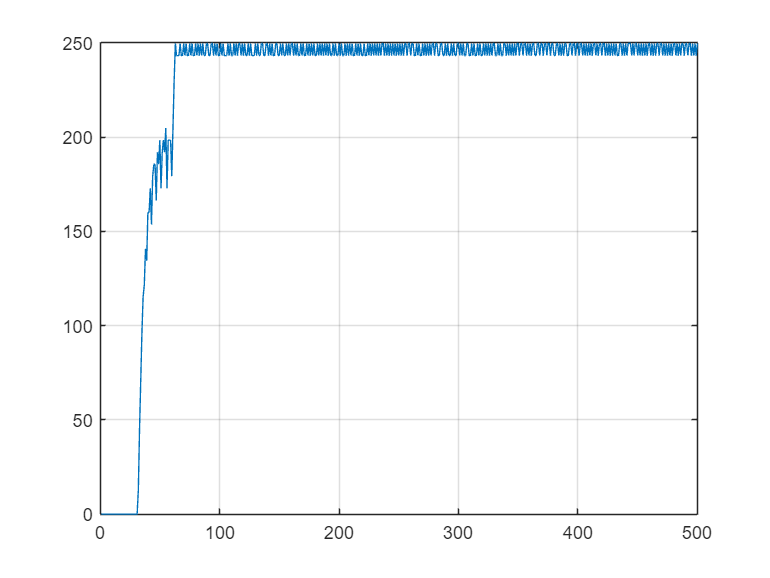


plot(y_train2);
grid on

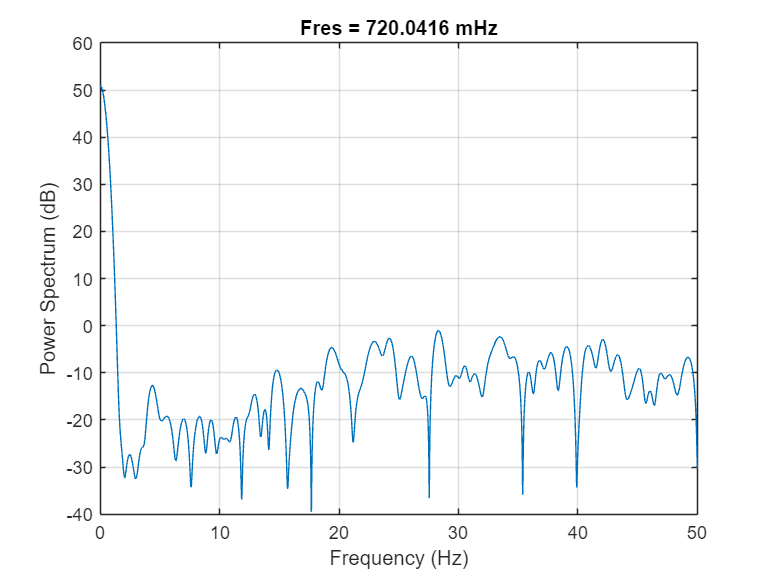


te = 0.01; %Perioada de esantionare
fs = 1/te; %Frecventa
fc = 0.2; %Frecventa de taiere

pspectrum(y_train1,fs,'Leakage',0,'TwoSided',false)

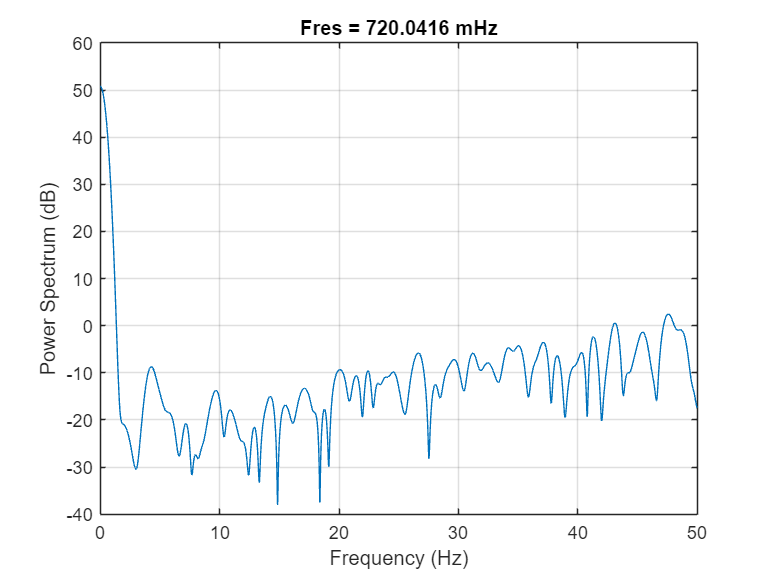


pspectrum(y_train2,fs,'Leakage',0,'TwoSided',false)

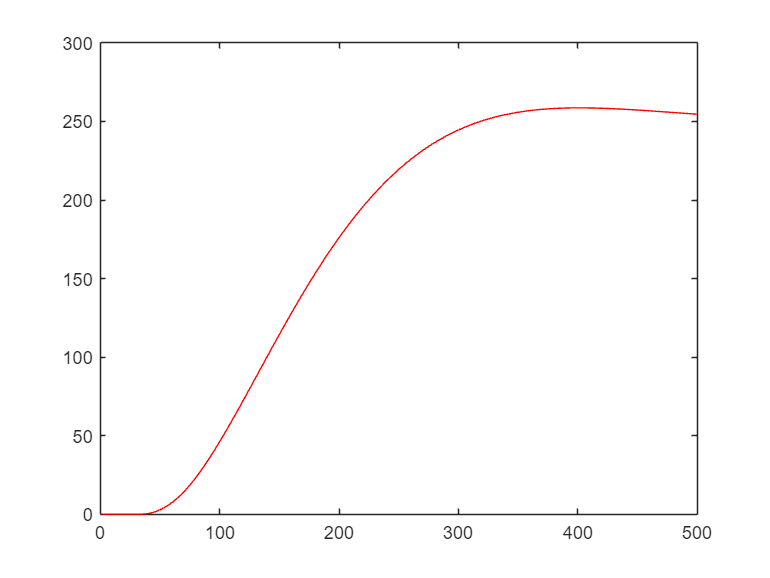


[b, a] = butter(2, fc/(fs/2),'low'); % coeficentii filtrului

y_filtrat1 = filter(b, a, y_train1); %filtrarea
y_filtrat2 = filter(b, a, y_train2); %filtrarea

plot(y_filtrat1,'r')

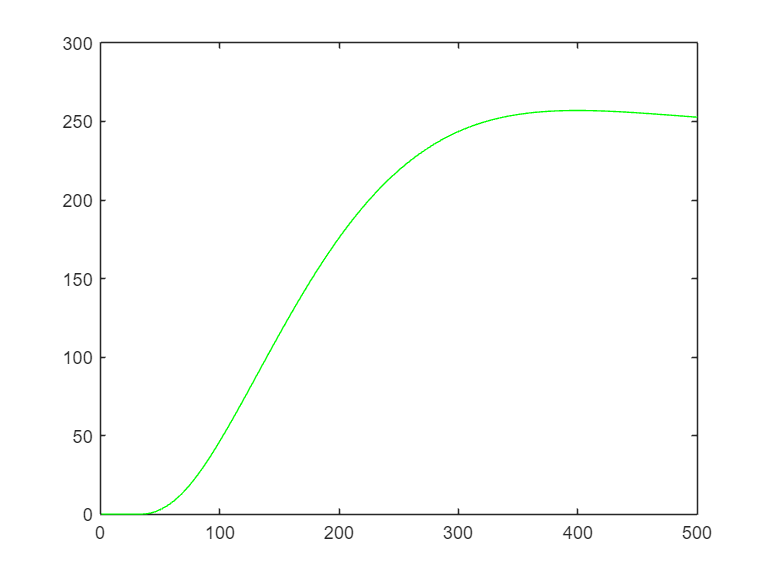

plot(y_filtrat2,'g')

Gp_m1 = tf(tf1_m1.Numerator,tf1_m1.Denominator)

Gp_m1 =
 
         1.335
  --------------------
  s^2 + 1.59 s + 1.388
 
Continuous-time transfer function.
Model Properties


Gp_m2 = tf(tf1_m2.Numerator,tf1_m2.Denominator)

Gp_m2 =
 
          1.339
  ---------------------
  s^2 + 1.596 s + 1.402
 
Continuous-time transfer function.
Model Properties


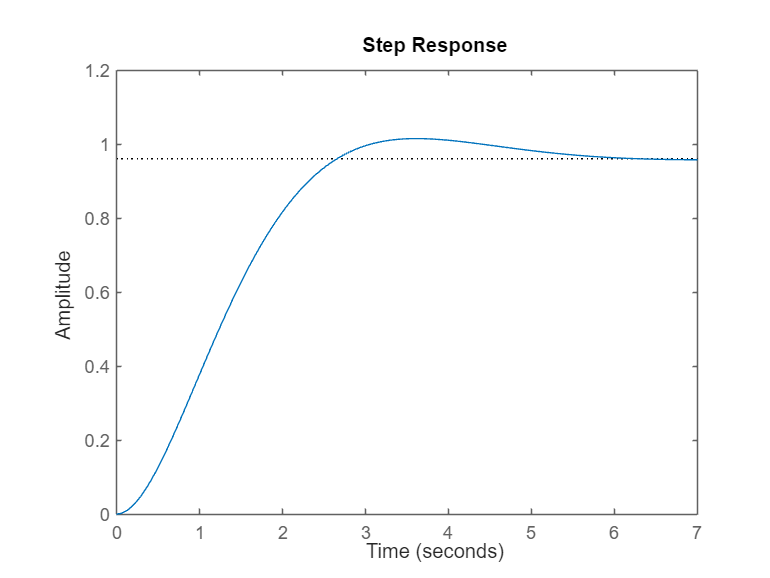

step(Gp_m1)

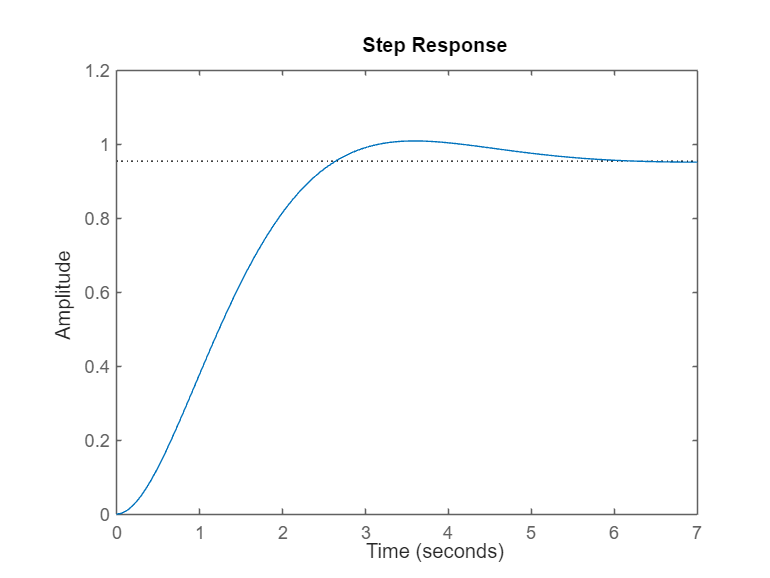

step(Gp_m2)

Gd1 = series(PID1, Gp_m1);
G1 = feedback(Gd1,1)

G1 =
 
          8822 s^2 + 8785 s + 1158
  -----------------------------------------
  s^4 + 1007 s^3 + 9759 s^2 + 9196 s + 1158
 
Continuous-time transfer function.
Model Properties


Gd2 = series(PID2, Gp_m2);
G2 = feedback(Gd2,1)

G2 =
 
          8820 s^2 + 8587 s + 609.3
  ------------------------------------------
  s^4 + 1007 s^3 + 9734 s^2 + 8988 s + 609.3
 
Continuous-time transfer function.
Model Properties


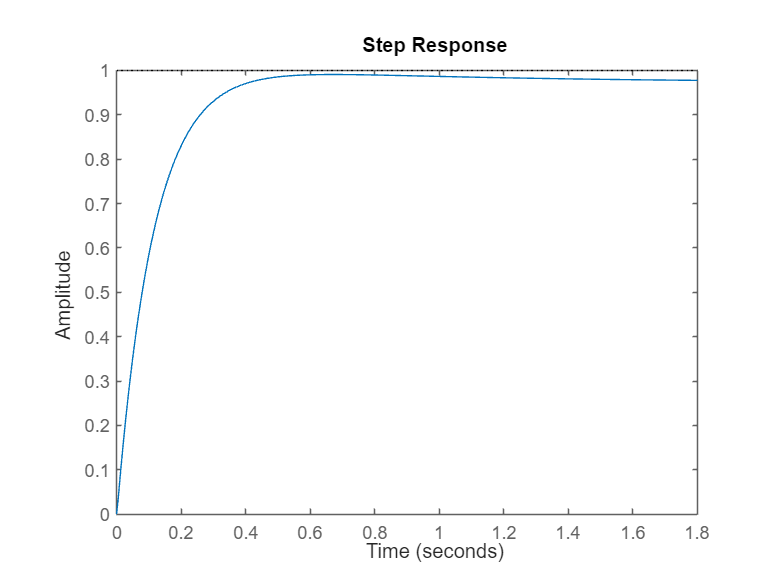

step(G1)

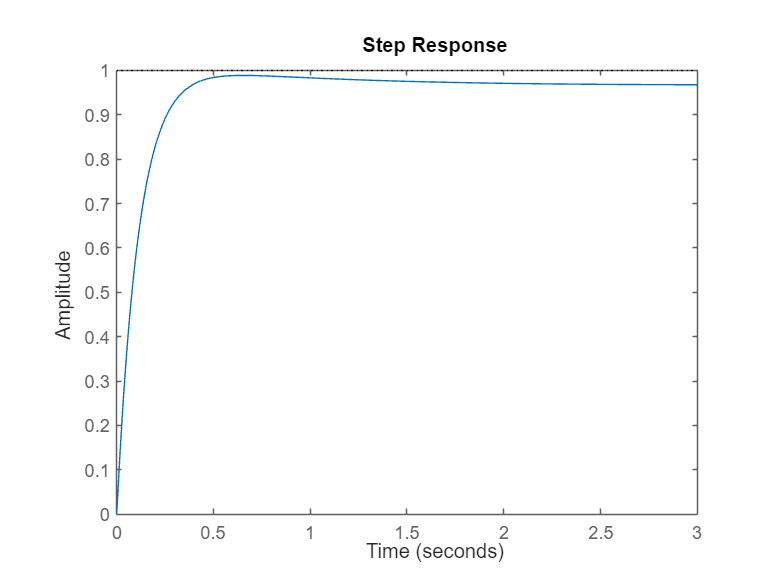

step(G2)


stepinfo(G1)

ans = struct with fields:
         RiseTime: 0.246151512154501
    TransientTime: NaN
     SettlingTime: NaN
      SettlingMin: 0.903970009558183
      SettlingMax: 0.990838041136845
        Overshoot: 0
       Undershoot: 0
             Peak: 0.990838041136845
         PeakTime: 0.669570656498778


stepinfo(G2)

ans = struct with fields:
         RiseTime: 0.246734969014870
    TransientTime: NaN
     SettlingTime: NaN
      SettlingMin: 0.903737510907938
      SettlingMax: 0.988780430758229
        Overshoot: 0
       Undershoot: 0
             Peak: 0.988780430758229
         PeakTime: 0.654627418500361


Regz1 = c2d(PID1,te,'foh');
Regz1 = tf(Regz1);
Regz1.Variable = 'z^-1';
[uzd1, yzd1] = tfdata(Regz1, 'v')

uzd1 = 1.0e+02 *

   3.572047718661726  -6.814152691028126   3.246370407114073


yzd1 =      1    -1     0



Regz2 = c2d(PID2,te,'foh');
Regz2 = tf(Regz2);
Regz2.Variable = 'z^-1';
[uzd2, yzd2] = tfdata(Regz2, 'v')

uzd2 = 1.0e+02 *

   3.500889802290250  -6.687701648935251   3.189017266702645


yzd2 =      1    -1     0
